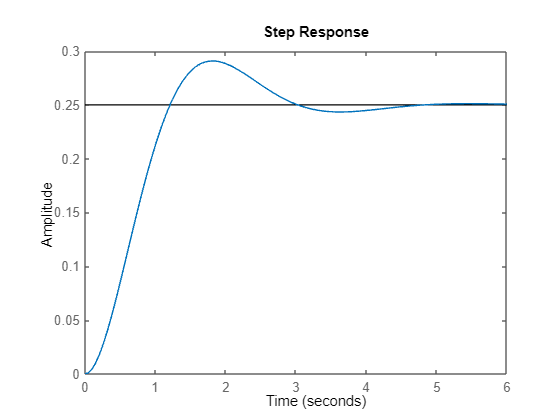

num = [0 0 1];
den = [1 2 3];

[nuc,dec] = cloop(num,den,-1);
step(nuc,dec)

***Digitalización de la planta***

nud1 =          0    0.0047    0.0044


ded1 =     1.0000   -1.7869    0.8231


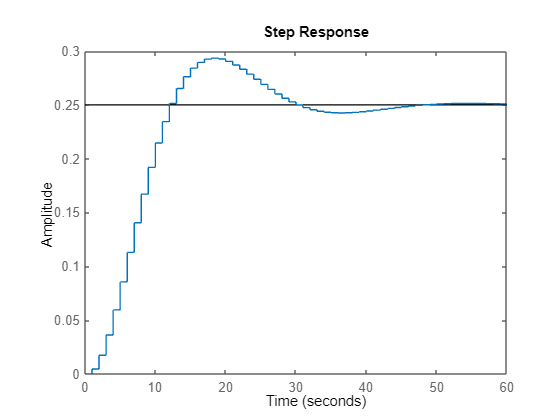

T = 0.1;
[nud,ded] = c2dm(num,den,T);
[nud1,ded1] = cloop(nud,ded,-1), dstep(nud1,ded1)

***Diseño del controlador***

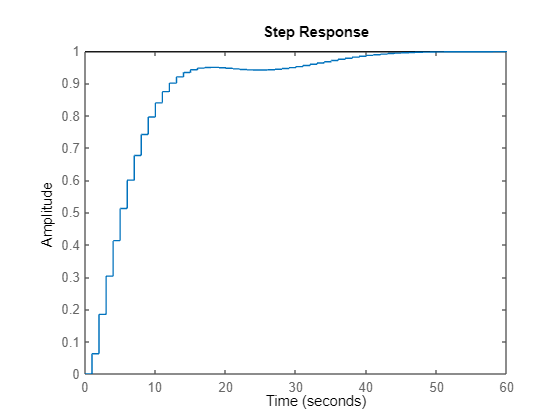

kp = 3;
ki = 0.4;
kd = 10;

nud1 = [(kp+ki+kd) -(kp+2*kd) kd];
ded1 = [1 -1 0];
% Controlador mas proceso
nud2 = conv(nud,nud1);
ded2 = conv(ded,ded1);

% Lazo cerrado
[nud3,ded3] = cloop(nud2,ded2,-1);
dstep(nud3 ,ded3)